% AOCS combined theta-e1 slew + SRP momentum desaturation model
%
% This script combines:
%   1) Commanded theta_e1 thrust-vector slew momentum
%   2) SRP disturbance torque momentum buildup
%
% Both momentum sources feed the same reaction wheel state.
%
% Combined wheel logic:
%   H_RW = H_RW + H_theta_e1 + integral(tau_SRP dt)
%
% Desaturation:
%   If |H_RW| >= 50 Nms, RCS unloads wheels to 5 Nms.
%
% Hydrazine:
%   DeltaH = r_RCS * impulse
%   impulse = m * Isp * g0
%   m = DeltaH / (r_RCS * Isp * g0)

clear;
clc;
close all;

%% Section 1: Load data

data = load('theta_e1_and_theta_e2.mat');

R_SC = data.R_SC;
theta_SP = data.theta_SP(:);
theta_e1 = data.theta_e1(:);
theta_e2 = data.theta_e2(:);
thrust_vector = data.thrust_vector;

N = size(R_SC,1);

%% Section 2: Define mission timing

mission_years = 16.79;
T_total = mission_years * 365.25 * 24 * 3600;
delta_t = T_total / (N-1);

time_years = ((0:N-1) .* delta_t) ./ (365.25*24*3600);

%% Section 3: Define spacecraft inertia and wheel limits

% Spacecraft inertia tensor [kg*m^2].
I_body = [ ...
    16912.28,     0.00,     2.42 ;
        0.00,  2610.23,     0.68 ;
        2.42,     0.68, 14892.69 ];

% Reaction wheel saturation limit [Nms].
RW_H_sat = 50;

% Momentum target after desaturation [Nms].
RW_H_target = 5;

%% Section 4: Define theta-e1 slew parameters

% Slew deadband threshold [rad].
% Smaller theta_e1 changes are ignored as numerical noise.
theta_deadband = deg2rad(0.001);

% Assumed slew rate for theta_e1 maneuvers.
% This converts commanded angle changes into wheel momentum using H = I*omega.
slew_rate_deg_s = 0.1;
slew_rate = deg2rad(slew_rate_deg_s);

% theta_e1 is treated as thrust-vector steering about body Z.
theta_e1_axis = [0 0 1];

%% Section 5: Define SRP parameters

% Solar constant at 1 AU [W/m^2].
G_SC = 1361;

% Speed of light [m/s].
c_light = 299792458;

% Optical multiplier.
% q = 1 for absorbing, q = 2 for perfectly reflecting.
q_srp = 1.5;

% Solar array area [m^2].
A_solar = 75.0;

% Effective solar-array center-of-pressure offset from spacecraft CG [m].
% This converts SRP force into SRP torque.
r_cp = 1.5;

% SRP torque direction.
% This assumes SRP torque loads the body Y axis.
srp_axis = [0 1 0];

% Conservative one-direction SRP buildup.
% true means SRP torque always builds in the same direction.
% false allows sign to follow theta_SP.
conservative_positive_srp = true;

% Approximate spacecraft-Sun distance history [AU].
% This assumes Earth departure near 1 AU and Themis arrival near 3.15 AU.
% Replace this with real heliocentric distance history if available.
r_AU = linspace(1.0, 3.15, N)';

%% Section 6: Define RCS hydrazine parameters

% Hydrazine RCS parameters.
Isp = 220;
g0 = 9.80665;

% Effective RCS moment arm for desaturation [m].
% This converts RCS linear impulse into angular impulse.
r_RCS = 1.5;

%% Section 7: Build validity mask

valid_k = true(N,1);

for k = 1:N
    if any(isnan(R_SC(k,:,:)),'all') || isnan(theta_SP(k)) || isnan(theta_e1(k))
        valid_k(k) = false;
    end
end

n_invalid = sum(~valid_k);

fprintf('Detected %d invalid timesteps\n', n_invalid);

Detected 171 invalid timesteps


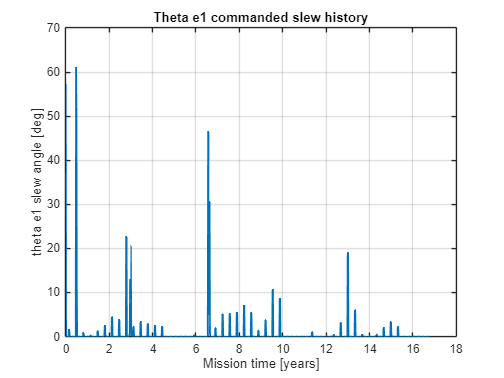


%% Section 8: Extract theta-e1 delta angles

dtheta_e1 = zeros(N-1,1);
dtheta_e2 = zeros(N-1,1);
theta_total = zeros(N-1,1);

for k = 1:N-1
    if ~valid_k(k) || ~valid_k(k+1)
        continue;
    end

    % Compute commanded steering angle changes [rad].
    dtheta_e1(k) = theta_e1(k+1) - theta_e1(k);
    dtheta_e2(k) = theta_e2(k+1) - theta_e2(k);

    % Use only theta_e1 in this combined model.
    theta_total(k) = abs(dtheta_e1(k));
end

%% Section 9: Compute SRP torque history

% theta_SP is interpreted as solar-panel incidence angle alpha [rad].
alpha = theta_SP;

% Solar radiation pressure [N/m^2].
% Wikipedia-style model:
% P_srp = q * G_SC/(c*R^2) * cos(alpha)^2
P_srp = q_srp .* (G_SC ./ (c_light .* r_AU.^2)) .* cos(alpha).^2;

% SRP force on the solar arrays [N].
F_srp = P_srp .* A_solar;

% SRP torque magnitude [Nm].
tau_srp_mag = F_srp .* r_cp;

% SRP torque vector [Nm].
tau_srp_vec = zeros(N,3);

for k = 1:N
    if conservative_positive_srp
        tau_srp_vec(k,:) = tau_srp_mag(k) .* srp_axis;
    else
        tau_srp_vec(k,:) = sign(theta_SP(k)) .* tau_srp_mag(k) .* srp_axis;
    end
end

%% Section 10: Propagate combined reaction wheel momentum

% Shared reaction wheel momentum state [Nms].
H_RW = zeros(N,3);
H_RW_mag = zeros(N,1);

% Store peak value before possible desaturation.
H_RW_peak = zeros(N,1);

% Theta-e1 slew bookkeeping.
slew_time_s = zeros(N-1,1);
slew_H_mag = zeros(N-1,1);
theta_e1_event_flag = false(N-1,1);

% Desaturation bookkeeping.
desat_count = 0;
desat_times = [];
desat_source = {};
m_RCS_vec = [];
H_dump_vec = [];
H_peak_desat_vec = [];

% Source-specific counts.
theta_e1_desat_count = 0;
srp_desat_count = 0;

% Substepping prevents missing SRP threshold crossings between trajectory samples.
substeps_per_interval = 100;

for k = 1:N-1

    % Start from previous combined wheel momentum.
    H_current = H_RW(k,:);

    if ~valid_k(k) || ~valid_k(k+1)
        H_RW(k+1,:) = H_current;
        H_RW_mag(k+1) = norm(H_current);
        continue;
    end

    % ---------------------------------------------------------------------
    % Part A: Accumulate SRP disturbance momentum over this trajectory step.
    % ---------------------------------------------------------------------

    dt_sub = delta_t / substeps_per_interval;
    tau_k = tau_srp_vec(k,:);

    for s = 1:substeps_per_interval

        % SRP angular momentum buildup:
        % H = H + tau*dt
        H_current = H_current + tau_k .* dt_sub;

        H_norm = norm(H_current);
        H_RW_peak(k+1) = max(H_RW_peak(k+1), H_norm);

        if H_norm >= RW_H_sat

            desat_count = desat_count + 1;
            srp_desat_count = srp_desat_count + 1;

            % Momentum before unloading.
            H_pre = H_current;

            % Unload to target while preserving momentum direction.
            H_post = H_pre .* (RW_H_target / H_norm);

            % Angular momentum removed by RCS [Nms].
            DeltaH = H_pre - H_post;

            % Hydrazine required for this desaturation.
            m_k = norm(DeltaH) / (r_RCS * Isp * g0);

            desat_times(end+1,1) = k;
            desat_source{end+1,1} = 'SRP';
            m_RCS_vec(end+1,1) = m_k;
            H_dump_vec(end+1,1) = norm(DeltaH);
            H_peak_desat_vec(end+1,1) = H_norm;

            % Reset wheel momentum after desaturation.
            H_current = H_post;

        end
    end

    % ---------------------------------------------------------------------
    % Part B: Add theta-e1 commanded slew momentum at this trajectory step.
    % ---------------------------------------------------------------------

    if abs(dtheta_e1(k)) > theta_deadband

        theta_e1_event_flag(k) = true;

        % Time required to execute this commanded slew.
        slew_time_s(k) = abs(dtheta_e1(k)) / slew_rate;

        % All theta_e1 slews are treated as positive-Z wheel momentum.
        omega1 = slew_rate .* theta_e1_axis;

        % Wheel momentum contribution from commanded slew.
        H_theta = (I_body * omega1')';

        slew_H_mag(k) = norm(H_theta);

        % Add commanded slew momentum to the same wheel state.
        H_current = H_current + H_theta;

        H_norm = norm(H_current);
        H_RW_peak(k+1) = max(H_RW_peak(k+1), H_norm);

        if H_norm >= RW_H_sat

            desat_count = desat_count + 1;
            theta_e1_desat_count = theta_e1_desat_count + 1;

            % Momentum before unloading.
            H_pre = H_current;

            % Unload to target while preserving momentum direction.
            H_post = H_pre .* (RW_H_target / H_norm);

            % Angular momentum removed by RCS [Nms].
            DeltaH = H_pre - H_post;

            % Hydrazine required for this desaturation.
            m_k = norm(DeltaH) / (r_RCS * Isp * g0);

            desat_times(end+1,1) = k;
            desat_source{end+1,1} = 'Theta_e1';
            m_RCS_vec(end+1,1) = m_k;
            H_dump_vec(end+1,1) = norm(DeltaH);
            H_peak_desat_vec(end+1,1) = H_norm;

            % Reset wheel momentum after desaturation.
            H_current = H_post;

        end
    end

    % Save final combined wheel state after SRP and theta-e1 for this step.
    H_RW(k+1,:) = H_current;
    H_RW_mag(k+1) = norm(H_current);

end

%% Section 11: Build theta-e1 event table

theta_event_idx = find(theta_e1_event_flag);
theta_event_count = length(theta_event_idx);

if theta_event_count > 0

    Event_ID = (1:theta_event_count)';
    Step = theta_event_idx(:);
    Mission_Time_yr = time_years(Step)';
    Theta_e1_deg = rad2deg(abs(dtheta_e1(Step)));
    Slew_Time_s = slew_time_s(Step);
    Slew_Time_min = Slew_Time_s ./ 60;
    Slew_H_Nms = slew_H_mag(Step);
    Wheel_H_After_Nms = H_RW_mag(Step+1);

    theta_e1_events_table = table( ...
        Event_ID, ...
        Step, ...
        Mission_Time_yr, ...
        Theta_e1_deg, ...
        Slew_Time_s, ...
        Slew_Time_min, ...
        Slew_H_Nms, ...
        Wheel_H_After_Nms);

else

    theta_e1_events_table = table();

end

%% Section 12: Build combined desaturation table

if desat_count > 0

    Desat_ID = (1:desat_count)';
    Step = desat_times(:);
    Mission_Time_yr = time_years(Step)';
    Source = string(desat_source(:));
    Peak_H_Nms = H_peak_desat_vec;
    Dumped_Momentum_Nms = H_dump_vec;
    Hydrazine_g = m_RCS_vec .* 1000;

    combined_desat_table = table( ...
        Desat_ID, ...
        Step, ...
        Mission_Time_yr, ...
        Source, ...
        Peak_H_Nms, ...
        Dumped_Momentum_Nms, ...
        Hydrazine_g);

else

    combined_desat_table = table();

end

%% Section 12b: Build top hydrazine consumption table

if desat_count > 0

    % Sort all desaturation events by hydrazine used.
    combined_desat_table_sorted = sortrows( ...
        combined_desat_table, ...
        'Hydrazine_g', ...
        'descend');

    % Display the largest hydrazine-consuming desaturation events.
    topN_hyd = min(15, height(combined_desat_table_sorted));

    top_hydrazine_table = combined_desat_table_sorted(1:topN_hyd,:);

else

    top_hydrazine_table = table();

end

%% Section 13: Plot theta-e1 and SRP histories

figure;
plot(time_years(1:N-1), rad2deg(theta_total), 'LineWidth',1.5);
xlabel('Mission time [years]');
ylabel('theta e1 slew angle [deg]');
title('Theta e1 commanded slew history');
grid on;

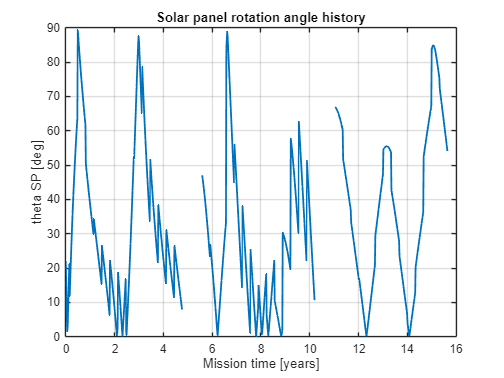


figure;
plot(time_years, rad2deg(theta_SP), 'LineWidth',1.5);
xlabel('Mission time [years]');
ylabel('theta SP [deg]');
title('Solar panel rotation angle history');
grid on;

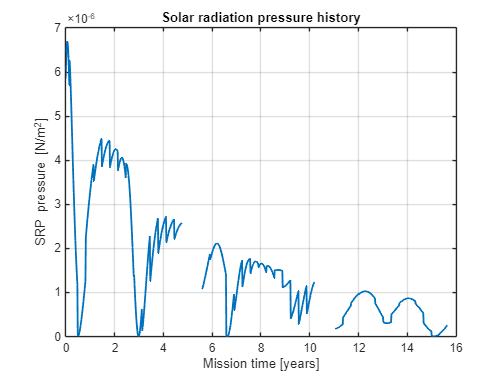


figure;
plot(time_years, P_srp, 'LineWidth',1.5);
xlabel('Mission time [years]');
ylabel('SRP pressure [N/m^2]');
title('Solar radiation pressure history');
grid on;

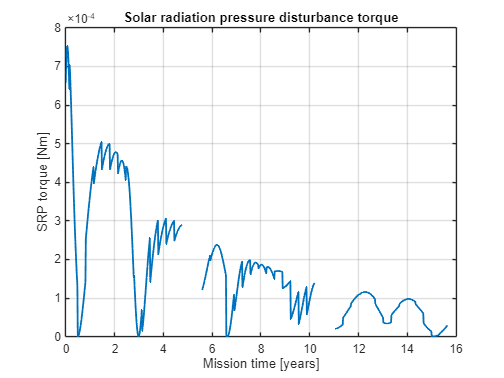


figure;
plot(time_years, tau_srp_mag, 'LineWidth',1.5);
xlabel('Mission time [years]');
ylabel('SRP torque [Nm]');
title('Solar radiation pressure disturbance torque');
grid on;

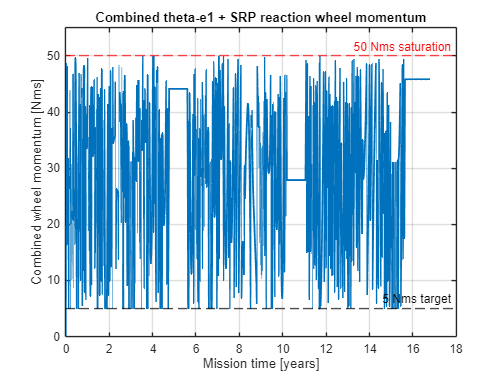


%% Section 14: Plot combined reaction wheel momentum

figure;
plot(time_years, H_RW_mag, 'LineWidth',1.5);
hold on;
yline(RW_H_sat, 'r--', '50 Nms saturation');
yline(RW_H_target, 'k--', '5 Nms target');
xlabel('Mission time [years]');
ylabel('Combined wheel momentum [Nms]');
title('Combined theta-e1 + SRP reaction wheel momentum');
ylim([0, max([RW_H_sat; H_RW_mag(:)]) * 1.10]);
grid on;

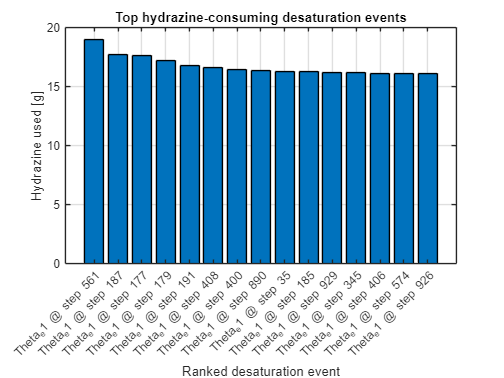


%% Section 14b: Plot top hydrazine-consuming desaturation events

if ~isempty(top_hydrazine_table)

    figure;

    bar(top_hydrazine_table.Hydrazine_g);

    xlabel('Ranked desaturation event');
    ylabel('Hydrazine used [g]');

    title('Top hydrazine-consuming desaturation events');

    grid on;

    % Add source labels under each bar.
    xticks(1:height(top_hydrazine_table));

    xticklabels( ...
        strcat( ...
            string(top_hydrazine_table.Source), ...
            " @ step ", ...
            string(top_hydrazine_table.Step)));

    xtickangle(45);

end


%% Section 15: Print combined mission summary

total_hydrazine_kg = sum(m_RCS_vec);

if ~isempty(H_peak_desat_vec)
    peak_momentum = max(H_peak_desat_vec);
else
    peak_momentum = max(H_RW_mag);
end

% Optional source-specific hydrazine totals.
if desat_count > 0
    source_vec = string(desat_source(:));
    srp_hydrazine_kg = sum(m_RCS_vec(source_vec == "SRP"));
    theta_e1_hydrazine_kg = sum(m_RCS_vec(source_vec == "Theta_e1"));
else
    srp_hydrazine_kg = 0;
    theta_e1_hydrazine_kg = 0;
end

fprintf('\n');
fprintf('--------------------------------------------------\n');

--------------------------------------------------


fprintf('Combined theta-e1 + SRP AOCS hydrazine summary\n');

Combined theta-e1 + SRP AOCS hydrazine summary


fprintf('--------------------------------------------------\n');

--------------------------------------------------


fprintf('Timesteps                         : %d\n', N);

Timesteps                         : 1019


fprintf('Valid timesteps                   : %d\n', sum(valid_k));

Valid timesteps                   : 848


fprintf('Invalid timesteps                 : %d\n', n_invalid);

Invalid timesteps                 : 171


fprintf('Mission duration                  : %.2f years\n', mission_years);

Mission duration                  : 16.79 years


fprintf('Trajectory delta_t                : %.2f s\n', delta_t);

Trajectory delta_t                : 520483.40 s


fprintf('Theta-e1 slew events              : %d\n', theta_event_count);

Theta-e1 slew events              : 165


fprintf('Total desaturation events         : %d\n', desat_count);

Total desaturation events         : 1731


fprintf('Desats triggered by SRP           : %d\n', srp_desat_count);

Desats triggered by SRP           : 1690


fprintf('Desats triggered by theta-e1      : %d\n', theta_e1_desat_count);

Desats triggered by theta-e1      : 41


fprintf('Peak combined wheel momentum      : %.4f Nms\n', peak_momentum);

Peak combined wheel momentum      : 66.4502 Nms


fprintf('Hydrazine from SRP desats         : %.6f kg\n', srp_hydrazine_kg);

Hydrazine from SRP desats         : 23.919203 kg


fprintf('Hydrazine from theta-e1 desats    : %.6f kg\n', theta_e1_hydrazine_kg);

Hydrazine from theta-e1 desats    : 0.655244 kg


fprintf('Total hydrazine used              : %.6f kg\n', total_hydrazine_kg);

Total hydrazine used              : 24.574447 kg


fprintf('--------------------------------------------------\n');

--------------------------------------------------


fprintf('Solar array area                  : %.3f m^2\n', A_solar);

Solar array area                  : 75.000 m^2


fprintf('SRP CP offset                     : %.3f m\n', r_cp);

SRP CP offset                     : 1.500 m


fprintf('RCS desat moment arm              : %.3f m\n', r_RCS);

RCS desat moment arm              : 1.500 m


fprintf('Min heliocentric distance         : %.3f AU\n', min(r_AU));

Min heliocentric distance         : 1.000 AU


fprintf('Max heliocentric distance         : %.3f AU\n', max(r_AU));

Max heliocentric distance         : 3.150 AU


fprintf('Peak SRP pressure                 : %.6e N/m^2\n', max(P_srp));

Peak SRP pressure                 : 6.691342e-06 N/m^2


fprintf('Peak SRP force                    : %.6e N\n', max(F_srp));

Peak SRP force                    : 5.018507e-04 N


fprintf('Peak SRP torque                   : %.6e Nm\n', max(tau_srp_mag));

Peak SRP torque                   : 7.527760e-04 Nm


fprintf('--------------------------------------------------\n');

--------------------------------------------------



if ~isempty(combined_desat_table)

    fprintf('\n');

    fprintf('Combined desaturation events\n');

    fprintf('--------------------------------------------------\n');

    disp(combined_desat_table);

end

Combined desaturation events


--------------------------------------------------


    Desat_ID    Step    Mission_Time_yr      Source      Peak_H_Nms    Dumped_Momentum_Nms    Hydrazine_g
    ________    ____    _______________    __________    __________    ___________________    ___________

         1        1               0        "SRP"           51.374            46.374              14.33   
         2        1               0        "SRP"           52.949            47.949             14.817   
         3        1               0        "SRP"           52.949            47.949             14.817   
         4        1               0        "SRP"           52.949            47.949             14.817   
         5        1               0        "SRP"           52.949            47.949             14.817   
         6        1


if ~isempty(top_hydrazine_table)

    fprintf('\n');

    fprintf('Top hydrazine-consuming desaturation events\n');

    fprintf('--------------------------------------------------\n');

    disp(top_hydrazine_table);

end

Top hydrazine-consuming desaturation events


--------------------------------------------------


    Desat_ID    Step    Mission_Time_yr      Source      Peak_H_Nms    Dumped_Momentum_Nms    Hydrazine_g
    ________    ____    _______________    __________    __________    ___________________    ___________

      1456      561          9.2361        "Theta_e1"       66.45             61.45             18.988   
       770      187          3.0677        "Theta_e1"      62.556            57.556             17.785   
       765      177          2.9028        "Theta_e1"      62.021            57.021              17.62   
       766      179          2.9358        "Theta_e1"       60.66             55.66             17.199   
       773      191          3.1337        "Theta_e1"      59.403            54.403             16.811   
      1181      408


if ~isempty(theta_e1_events_table)

    fprintf('\n');

    fprintf('Theta-e1 slew events\n');

    fprintf('--------------------------------------------------\n');

    disp(theta_e1_events_table);

end

Theta-e1 slew events


--------------------------------------------------


    Event_ID    Step    Mission_Time_yr    Theta_e1_deg    Slew_Time_s    Slew_Time_min    Slew_H_Nms    Wheel_H_After_Nms
    ________    ____    _______________    ____________    ___________    _____________    __________    _________________

        1         1               0            57.296         572.96           9.5493        25.993           27.324      
        2        10         0.14844            1.5232         15.232          0.25386        25.993           28.498      
        3        11         0.16493            1.5232         15.232          0.25386        25.993           26.469      
        4        30          0.4783            61.016         610.16           10.169        25.993            2